### **Comparison of network structures: training**

In this case a pretrained convolutional model and a fully connected model are trained using the LibriSpeech dataset 

Start by loading the pretrained convolutional network:

doLoadmyModels = false

doLoadmyModels = logical
   0



if doLoadmyModels
    load libriconv.mat
    load librifcon.mat
else

    load preTrainConv.mat %convolutional pretrained model
    load preTrainFull.mat %fully connected
end

Load the dataset - in this case, the open-source LibriSpeech, from my own folder:

dataset = fullfile("LibriSpeech"); 
trainDataVoices = audioDatastore(fullfile(dataset,"train-clean-100"),...
    "IncludeSubfolders",true);

samplesIncluded = 80; %load only a section of the dataset
trainDataVoices = shuffle(trainDataVoices);
trainDataVoices = subset(trainDataVoices,1:samplesIncluded);
fs = 16000; %to be extracted from data? -in case we use another dataset

[noise, fsNoise] = audioread("WashingMachine-16-8-mono-1000secs.mp3");

**Prepare Tall arrays for training**

load data for training into tall-array format



audioData = readall(trainDataVoices);

%set values for data to be segmented
segments = 8;
%NOTICE: window is 256, input features will be 129
window = sqrt(hann(256,'periodic')); 
overlap = round(length(window)*0.5);

dftSize = length(window); 

T = tall(audioData); 

%downsampling script here...

[targets, predictors, magnitudes] = cellfun(...
    @(x)prepare_data(x,...
        fs,...
        noise,...
        window,...
        overlap,...
        dftSize ...
        ), ...
    T, ...
    UniformOutput=false ...
); 

[targets, predictors, magnitudes] = gather(targets, predictors, magnitudes);

predictors = cat(3,predictors{:});
noisyMean = mean(predictors(:));
noisyStd = std(predictors(:));
predictors(:) = (predictors(:) - noisyMean)/noisyStd;

targets = cat(2,targets{:});
cleanMean = mean(targets(:));
cleanStd = std(targets(:));
targets(:) = (targets(:) - cleanMean)/cleanStd;

%reshape
predictors = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));
targets = reshape(targets,1,1,size(targets,1),size(targets,2));

%% split into training and validation

features = dftSize*0.5;

inds = randperm(size(targets,4));
L = floor(0.90*size(targets,4));

trainPredictors = predictors(:,:,:,inds(1:L));
trainTargets = targets(:,:,:,inds(1:L));

validatePredictors = predictors(:,:,:,inds(L+1:end));
validateTargets = targets(:,:,:,inds(L+1:end));

miniBatchSize = floor(samplesIncluded*0.20);
options = trainingOptions("adam", ...
    MaxEpochs=3, ...
    InitialLearnRate=1e-5, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationFrequency=floor(size(trainPredictors,4)/miniBatchSize), ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ... 
    LearnRateDropPeriod=1, ...
    ValidationData={validatePredictors,permute(validateTargets,[3 1 2 4])});

%% Train the convolutional network

    convNet = trainNetwork(...
        trainPredictors, ...
        permute(trainTargets,[3 1 2 4]), ...
        denoiseNetFullyConvolutional.Layers, ...
        options ...
    );

Train the fully connected network:

miniBatchSize = floor(samplesIncluded*0.20);
options = trainingOptions("adam", ...
    MaxEpochs=3, ...
    InitialLearnRate=1e-5, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationFrequency=floor(size(trainPredictors,4)/miniBatchSize), ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ... 
    LearnRateDropPeriod=1, ...
    ValidationData={validatePredictors,validateTargets});

    fullNet = trainNetwork(...
        trainPredictors, ...
        trainTargets, ...
        denoiseNetFullyConnected.Layers, ...
        options ...
    );

### **Evaluation**

Using a new instance of data; reformat to the input dimensions of the models, do prediction, and convert back into a time-domain audio signal (using phases recovered from noisy data).

[testAudio, testFs] = audioread("8555-292519-0015.flac");
audio = mydownsample(testAudio,testFs,8000); %downsample to 8 kHz

[testTarget, testPredictor, testMagnitude] = prepare_data(testAudio, testFs, noise, window, overlap, dftSize);

testPredictor = cat(3, testPredictor);
noisyMeanT = mean(testPredictor(:));
noisyStdT = std(testPredictor(:));
testPredictor(:) = (testPredictor(:) - noisyMeanT)/noisyStdT;

 testTarget = cat(2, testTarget);
 cleanMeanT = mean(testTarget(:));
 cleanStdT = std(testTarget(:));
 testTarget(:) = (testTarget(:) - cleanMeanT)/cleanStdT;

testPredictor = reshape(testPredictor,size(testPredictor,1),size(testPredictor,2),1,size(testPredictor,3));
% testTarget = reshape(testTarget,1,1,size(testTarget,1),size(testTarget,2));

Make a prediction with convolutional net

speech = predict(convNet, testPredictor);

noisePhase = angle(testMagnitude);

speech(:) = cleanStdT*speech(:) + cleanMeanT;

speech = squeeze(speech(:,:,:,1:end-1)).* exp(1j*noisePhase); 

speech = [conj(speech(end-1:-1:2,:)); speech];

Plot the prediction

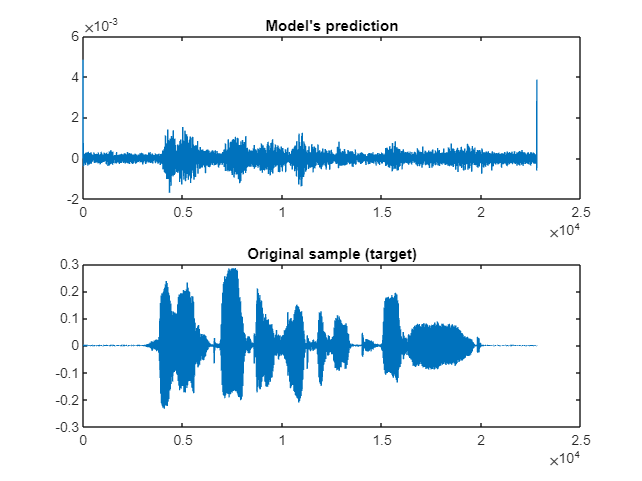

speechReconstruct = istft(speech, testFs, ...
    "Window", window, "OverlapLength", overlap, ... 
    "FFTLength", dftSize, "ConjugateSymmetric", true);

figure,
subplot(2,1,1), plot(speechReconstruct), title("Model's prediction");
subplot(2,1,2), plot(audio), title("Original sample (target)");

Remove the amplitude offset (TODO: find the cause of this!)

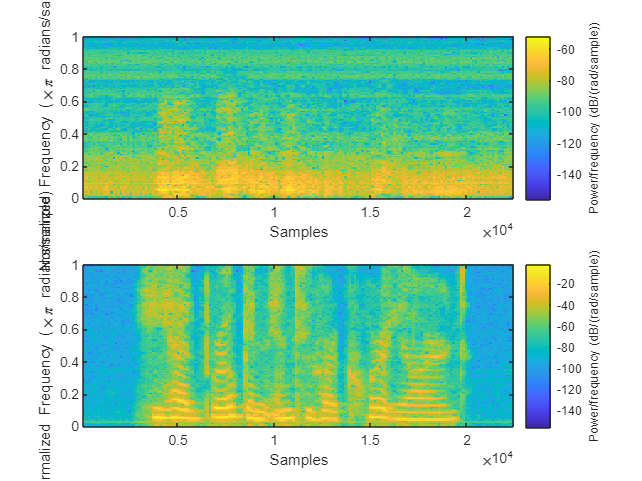

%get rid of the rather significant amplitude error
offset=100;
speechAug = speechReconstruct(offset:end-offset);
audioAug = single(audio(offset:length(speechAug)+offset-1)); %augment target to have same dimensions

%figure, plot(speechAug)
figure, 
subplot(2,1,1), title("prediction"), spectrogram(speechAug, window, overlap, dftSize, 'yaxis');
subplot(2,1,2), title("target"), spectrogram(audioAug, window, overlap, dftSize, 'yaxis');

Objective measurements:

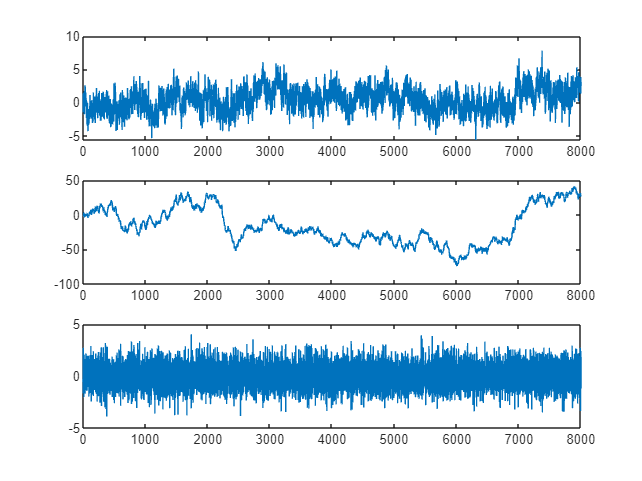

%mean squared error:

SI-SDR

sisdr(speechAug, audioAug)

ans = single
-3.9515

The scale-invariant signal-to-distortion ratio (SI-SDR) makes an estimate about the noise (or residual) that is orthogonal to the target signal by adding a scaling factor `alpha` to the target (thus achieving a faster and more efficient algorithm for estimation than classic signal-to-noise ratio and signal to ) [1]. 

function metric = sisdr(y,target)
%sisdr Scale-Invariant Signal-to-Distortion Ratio (SDR)
% metric = sisdr(estimate,target) calculates the scale-invariant SDR
% described in [1].

y = y - mean(y,1);
target = target - mean(target,1);

alpha = sum(y.*target,1)./(sum(target.^2,1) + eps);

etarget = alpha.*target;
eres = y - etarget;

top = sum(etarget.^2);
bottom = sum(eres.^2);
metric = 10*log(top./(bottom+eps))/log(10);

end

[1] LE ROUX, Jonathan, et al. [SDR–half-baked or well done?](https://doi.org/10.1109/ICASSP.2019.8683855). In: *ICASSP 2019-2019 IEEE International Conference on Acoustics, Speech and Signal Processing (ICASSP)*. IEEE, 2019. p. 626-630.